# Separating Stimulus, Saccade and Buttonpress

This example has been used in the unfold toolbox paper Ehinger & Dimigen 2018. For more details on the experiment please have a look there!

warning off
init_unfold


Starting unfold toolbox.
Adding subfolders and other toolboxes to path...
Done.


warning on

# Introduction

Subjects are exploring a face stimulus. Using an eyetracker and the EEG-Eye toolbox we add markers of saccade onsets, stimulus onsets and button presses into our EEG-Data. The data were cleaned for eye-movement related artefacts using ICA.

In this tutorial we try to disentangle stimulus related ERPs, buttonpress ERPs and (micro)saccade related ERPs.

EEG  = pop_loadset('C:\Users\behinger\Dropbox\deconv_olaf\workshop\data\facestudy_integrated.set')

pop_loadset(): loading file C:\Users\behinger\Dropbox\deconv_olaf\workshop\data\facestudy_integrated.set ...


EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

% In order to understand better, we will rename some events
for e = 1:length(EEG.event)
    switch EEG.event(e).type
        case {'S121','S122','S123'}
            EEG.event(e).type = 'stimulus';
        case {'S255'}
            EEG.event(e).type = 'button';
    end
end

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

EEG = struct with fields:
             setname: 'Face discrimination'
            filename: 'facestudy_integrated.set'
            filepath: 'C:\Users\behinger\Dropbox\deconv_olaf\workshop\data'
             subject: '11'
               group: ''
           condition: ''
             session: []
            comments: [2×108 char]
              nbchan: 1
              trials: 1
                pnts: 1035202
               srate: 250
                xmin: 0
                xmax: 4.1408e+03
               times: [1×1035202 double]
                data: [1×1035202 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×1 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×3241 struct]
             urevent: [1×3241 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''  ''}
               epoc

# Running the toolbox

cfgDesign = [];
cfgDesign.eventtypes = {'saccade','stimulus','button'}; % we model the saccadeonset, stimulusonset and buttonpress
cfgDesign.formula = {'y ~ 1 + spl(sac_amplitude,10)','y~1','y~1'}; % For splines see the spline tutorial
EEG = uf_designmat(EEG,cfgDesign);

Multiple events with separate model-formula detected
Modeling 3241 event(s) of [saccade] using formula: y~1 
The spline that got removed due to collinearity in the basis set (as intended) for the effect sac_amplitude has its peak at 1.270010
This does not mean that the event-intercept represents this value! 
Modeling 3241 event(s) of [stimulus] using formula: y~1 
Modeling 3241 event(s) of [button] using formula: y~1 


Timexpand everything:

cfgTimeexpand = [];
cfgTimeexpand.timelimits = [-0.8 0.6];

EEG = uf_timeexpandDesignmat(EEG,cfgTimeexpand);


uf_timeexpandDesignmat(): Timeexpanding the designmatrix...
...done


Fit the GLM (solve $\mu =X_{\mathrm{dc}} \beta$ for $\beta \;$)

EEG = uf_glmfit(EEG);


uf_glmfit(): Fitting deconvolution model...solving the equation system

solving electrode 1 (of 1 electrodes in total)... 88 iterations, took 1.6s
 LMfit finished 


# Massive-Univariate Model (without deconvolution)

it is nice to compare deconvolution results with the results of a normal massive-univariate regression (this regression will be identical to a simple ERP for stimulus & response). To do so, we need to epoch our data and fit a linear model for each timepoint/electrode separately.

EEG_epoch = uf_epoch(EEG,'timelimits',cfgTimeexpand.timelimits);

pop_epoch():2760 epochs selected
Epoching...
pop_epoch():2760 epochs generated
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 


EEG_epoch = uf_glmfit_nodc(EEG_epoch);

% Unfold does not overwrite the deconv-betas, but can keep both at the same time

# Combine results & plot

ufresult = uf_condense(EEG_epoch);
% ufresult.beta      => deconvolved
% ufresult.beta_nodc => Massive-Univariate

% evaluate the spline at some points of the continuous saccade-amplitude spectrum
ufresult = uf_predictContinuous(ufresult,'predictAt',{{'sac_amplitude',0.75:0.5:3.5}})

ufresult = struct with fields:
       unfold: [1×1 struct]
        times: [1×350 double]
     chanlocs: [1×1 struct]
        param: [1×9 struct]
    beta_nodc: [1×350×9 double]
         beta: [1×350×9 double]



% We always only plot one predictor. The quesiton is, at what value of the other predictors, should we look at it?
% Here we look at one predictor when all other predictors are at their respective mean value.
ufresult = uf_addmarginal(ufresult);

uf_addmarginal: working on field beta_nodc 
re-running uf_condense to recover unconverted splines 
uf_addmarginal: working on field beta 
re-running uf_condense to recover unconverted splines 



plotting all parameters

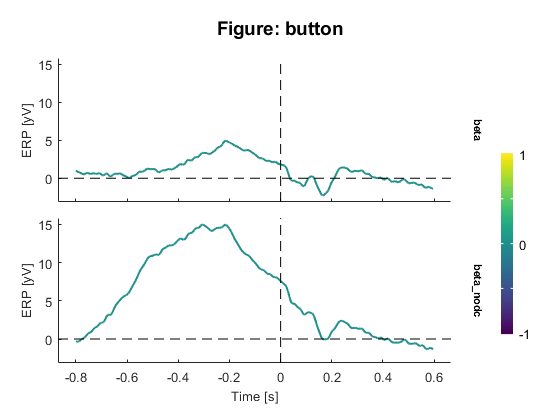

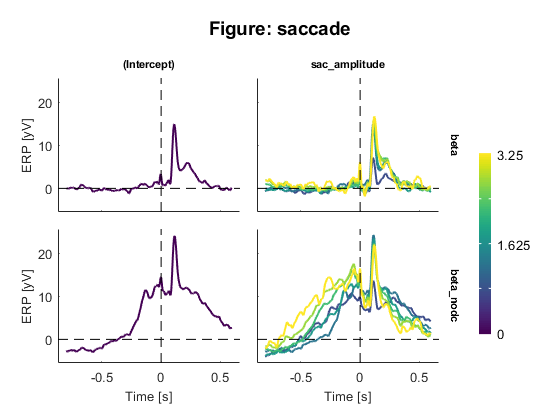

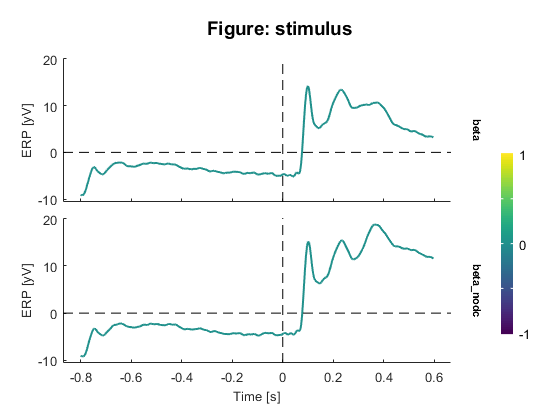


% Plot them
uf_plotParam(ufresult,'channel',1,'plotSeparate','event');

It is very apparent that much of the button-press related activity visible in the "no-deconvolution" (classical ERP) condition is removed by the deconvolution. The same holds true for the saccade effect. The stimulus effect is also different, but only at later time points (~250ms).